## ROBOTICS PROJECT

clear all

Definizione degli agenti, posizioni casuali e orientamenti casuali  (3D)

settare la comunicazione con handshaking (common network)

*definizione: fatto*

*manca settare la rete *

% initialize UGV struct
ugv.xw = 0;  ugv.yw = 0; ugv.hw = pi/4;    % robot position and orientation wrt world frame
ugv.xr = 0;  ugv.yr = 0; ugv.hr = 0;    % robot position and orientation wrt its frame

% define position of visual features of UGV
ugv.P1 = [0.2; 0.15; 0.2];      %[m]
ugv.P2 = [0.2; -0.15; 0.2];     %[m]
ugv.P3 = [-0.2; -0.15; 0.2];    %[m]
ugv.P4 = [-0.2; 0.15; 0.2];     %[m]

% !!! pose wrt its frame is needed only to have the right arrays and matrices dimension

% initialize AUV struct - line formation

auv.n  = 5;                             % number of auvs

auv.id =    zeros(auv.n,1);             % auv id 
auv.xw =    rand(auv.n,1)*6-3 ;         % coords in world frame
auv.yw =    rand(auv.n,1)*6-3 ;
auv.zw =    0.1*ones(auv.n,1);

auv.rollw  =  zeros(auv.n,1);           % roll angle in world frame
auv.pitchw =  zeros(auv.n,1);           % pitch angle in world frame
auv.yaww   =  rand(auv.n,1)*2*pi;       % yaw angle in world frame

auv.xr = auv.xw - ugv.xw;               % coords in robot frame (UGV)
auv.yr = auv.yw - ugv.yw;  
auv.zr = auv.zw; 

auv.rollr = auv.rollw ; 
auv.pitchr = auv.pitchw;
auv.yawr = auv.yaww - ugv.hw;

% camera parameters:

cam.fov.x = 1.2572;                                 % vertical  fov [rad]
cam.fov.y = 1.4408;                                 % orizontal fov [rad]
cam.f = 3.6*10^-3;                                  % focal length  [m]
cam.ImagePlaneSize = [6.32*10^-3  4.74*10^-3];      % Y x X         [m  m]
cam.PixelDensity = [4000  3000];                    % Y x X - adimensional


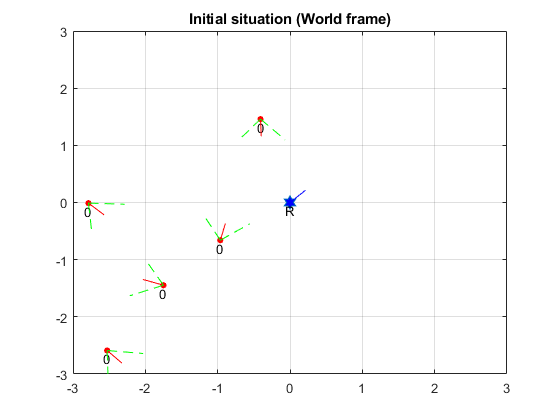

%% visualize the initial situation

% generate labels for plot
labels = generateLabels(auv);

% plot the situation
figure(1);
plotFlock(auv,ugv,cam,labels);
axis([-3 3 -3 3]);
grid on;

title('Initial situation (World frame)');

Definizione traiettoria ugv, e generiamo la traiettoria controllata da simulink (2D)

*fatto (volendo migliorare il controllore di simulink)*

definizione decollo degli uav e generazione trajectory in simulink (3D)

*fatto*  

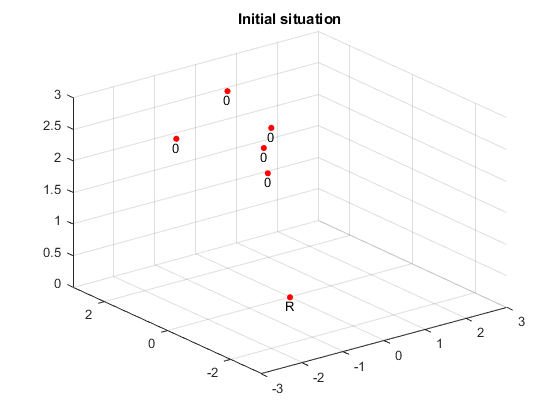

auv.zr = 3 * ones(auv.n,1);

%% visualize the situation after take-off
figure(2);
plot3([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],'or','MarkerSize',4,'MarkerFaceColor','r')
text([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],labels,'VerticalAlignment','top','HorizontalAlignment','center')
axis([-3 3 -3 3])   
title('Initial situation');
grid on;

I droni cercano di vedere l'ugv con la telecamera con movimenti e rotazioni casuali (3D)

dal momento in cui un drone vede l'ugv, lo comunica, ed entra nella rete di formazione (formation network)

*da aggiungere: *

*-la semplice rotazione basta per trovare il robot prima o poi, ma se il drone è stato spawnato troppo vicino al robot, non lo vedrà mai, perchè il robot si trova esattamente sotto di lui.*

*Si potrebbe aggiungere che se dopo aver fatto il giro completo su se stesso, il drone ancora non vede il robot, indietreggia di tot m, e ricomincia a girare.*

*- lo schema e il calcolo del grafo con le varie matrici ogni volta che la formazione (quindi la rete) cambia perchè si è aggiunto qualcuno.*

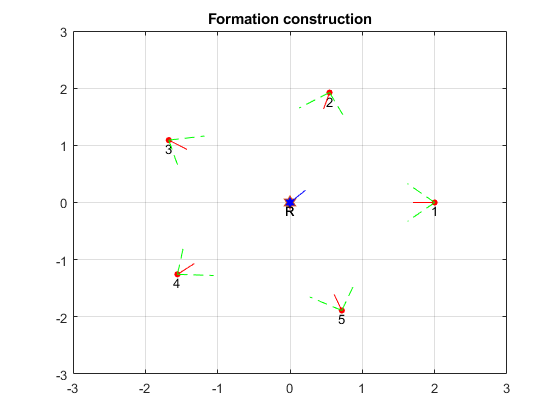

out_auv = auv;

% create the formation struct
form_auv.n = 0;
new = false;
form_complete = false;

max_it = 200;
it = 1;


% auv search the robot
while(form_auv.n~=auv.n || form_complete == false)
    
    labels_out = generateLabels(out_auv);
    labels_form = generateLabels(form_auv);
    
    figure(3);
    plotFlock(out_auv,ugv,cam,labels_out);
    hold on;
    plotFlock(form_auv,ugv,cam,labels_form);
    hold off;
    axis([-3 3 -3 3]);
    grid on;
    title("Formation construction")
    it=it+1;
    pause(.01)
    
    %% --------------- AUVS NOT IN FORMATION
    % check if auvs not in formation see the robot
    rem = [];
    for i = 1 : out_auv.n
        AGV.pos = [out_auv.xr(i) out_auv.yr(i) out_auv.zr(i)];
        AGV.rpy = [out_auv.rollr(i) out_auv.pitchr(i) out_auv.yaww(i)];
        
        [AGV.insideIP,AGV.v,AGV.u] = computeCameraImage(AGV.pos,AGV.rpy,[0 0 0]);

        if(AGV.insideIP)    
            % add the auv to the formation  
            out_auv.id(i) = form_auv.n+1;
            form_auv = addToFormation(form_auv,out_auv,i);
            rem(end+1) = i;    
            new = true;
        else
            out_auv.yaww(i) = out_auv.yaww(i)+0.02;
        end
    end
    out_auv = removeAuvFrom(out_auv, rem);

        
    %% --------------- AUVS IN FORMATION
    if(form_auv.n > 1) 
        form_auv = consensusPolarFormation(form_auv,ugv,2,new);
        form_auv.yaww = pi+form_auv.th;
        new = false;
        if(max(form_auv.travel_dist) < 0.01)
            form_complete = true;
        else
            form_complete = false;
        end
    end
    
    if(it == max_it)
        break;
    end
end


if(form_auv.n==auv.n || form_complete == true)
txt = sprintf('Every auv is in formation after %d iterations',it);
elseif(form_auv.n~=auv.n || form_complete == true)
txt = sprintf('Formation complete with some auv missing after %d iterations',it);
elseif(form_auv.n==auv.n || form_complete == false)
txt = sprintf('Every auvs is pointing to the robot but the formation is not ready %d iterations',it);
else
txt = sprintf('Fail after max iterations, try to increase max_it')    
end


consenso della formazione offline  (2D) 

*fatto, da modificare per avere meno iterazioni a discapito di eventuali sovrapposizioni, che non sono più un problema   GIOELE*

una volta che le posizioni della formazione sono ben definite (con un threshold sulla convergenza) 

si va in formazione (3D) con la traiettoria calcolata (traj relativa tra loro pos e ugv)

*calcolo traiettoria e generarla con simulink*

#### ciclo: (ogni 0.5 s consenso sul movimento UGV, e per ora verificare quanto si rovina la formazione, poi, aggiungere consenso formazione ogni tot)

una volta in formazione UGV si muove, 

lettura con la camera -> imageplane

imageplane -> pose recovery (misura sporca di rototransl)

*ricavare tutte le rototranslazioni e usare pose recovery che è già fatta*

consensus sulla posizione del ugv k-1 (consensus average sulla posizione del ugv dopo che si è mosso)  (2D)

*da fare *

calcolo traiettoria droni per mantenere CoM, con controllo yaw per mantere ugv all'interno dell'image plane

attuazione della traiettoria se fattibile con simulik, altrimenti, semplicemente in 2D qui

*da fare*